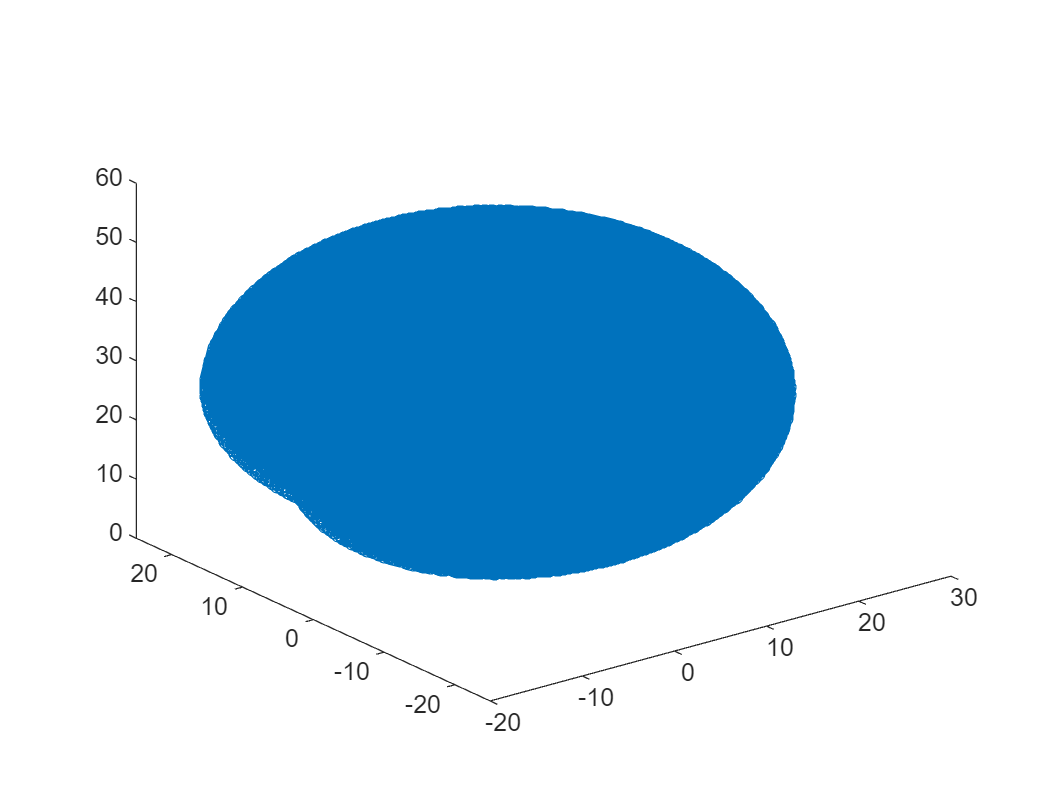

clc
clear

L1 = 30;
L2 = 15;
L3 = 10;

n = 50;

theta1 = linspace(-140,140,n);
theta2 = linspace(-120,120,n);
theta3 = linspace(-110,110,n);

theta1 = theta1';
theta2 = theta2';
theta3 = theta3';

px = zeros(n*n*n,1);
py = zeros(n*n*n,1);
pz = zeros(n*n*n,1);

m = 1;

for i = 1 : n
    for j = 1 : n
        for k = 1 : n

            x = cosd(theta1(i,1))*(L3*cosd(theta2(j,1) + theta3(k,1)) + L2*cosd(theta2(j,1)));
            y = sind(theta1(i,1))*(L3*cosd(theta2(j,1) + theta3(k,1)) + L2*cosd(theta2(j,1)));
            z = L1 + L3*sind(theta2(j,1) + theta3(k,1)) + L2*sind(theta2(j,1));

            px(m,1) = x;
            py(m,1) = y;
            pz(m,1) = z;

            m = m + 1;

        end
    end
end

plot3(px,py,pz,'o')